clear;
global SAVE_EXT;
global SAVE_DIR;
SAVE_EXT = ".png";% figure saving conf (png, eps, etc...)
SAVE_DIR = "./tex/images/";
% addpath("../CVX-arm64/");
% cvx_setup;
mkdir(SAVE_DIR);


k_1 = 7.29;
a_0_1 = 1;
T_1 = 0.38;
xi = 0;
k_2 = 9.46;
a_0_2 = 1;
T_2 = 1;
T = 0.25;
A_g = 7.68;
omega_g = 0.3;

## Task 1

TF_plant = tf([k_2], [T_2, a_0_2]) * tf([k_1], [T_1, a_0_1]);
ss_plant_continious = ss(TF_plant);
poles_ss_plant_continious = pole(ss_plant_continious);
ss_plant_discrete = c2d(ss_plant_continious, T)

ss_plant_discrete =
 
  A = 
            x1       x2
   x1   0.3581  -0.2104
   x2   0.3198   0.9387
 
  B = 
           u1
   x1   1.279
   x2  0.3728
 
  C = 
          x1     x2
   y1      0  11.34
 
  D = 
       u1
   y1   0
 
Sample time: 0.25 seconds
Discrete-time state-space model.


eig(ss_plant_discrete.A)

ans =     0.5179
    0.7788


Gamma = [0 1; 0 0];
H = [1 1];
assert(rank(ctrb(ss_plant_discrete.A, ss_plant_discrete.B)) == 2);
assert(rank(obsv(Gamma, H)) == 2);
model_disc = c2d(ss(Gamma, [0; 0], H, 0), T);
eig(Gamma), eig(model_disc.A)

ans =      0
     0


ans =      1
     1


M = sylvester(ss_plant_discrete.A, -Gamma, ss_plant_discrete.B * H);
K_1 = H * inv(M)

K_1 =     0.6122    1.3780


ss_plant_discrete.A - ss_plant_discrete.B * K_1, eig(ss_plant_discrete.A - ss_plant_discrete.B * K_1)

ans =    -0.4250   -1.9729
    0.0915    0.4250


ans = 1.0e-08 *

   -0.5460
    0.5460


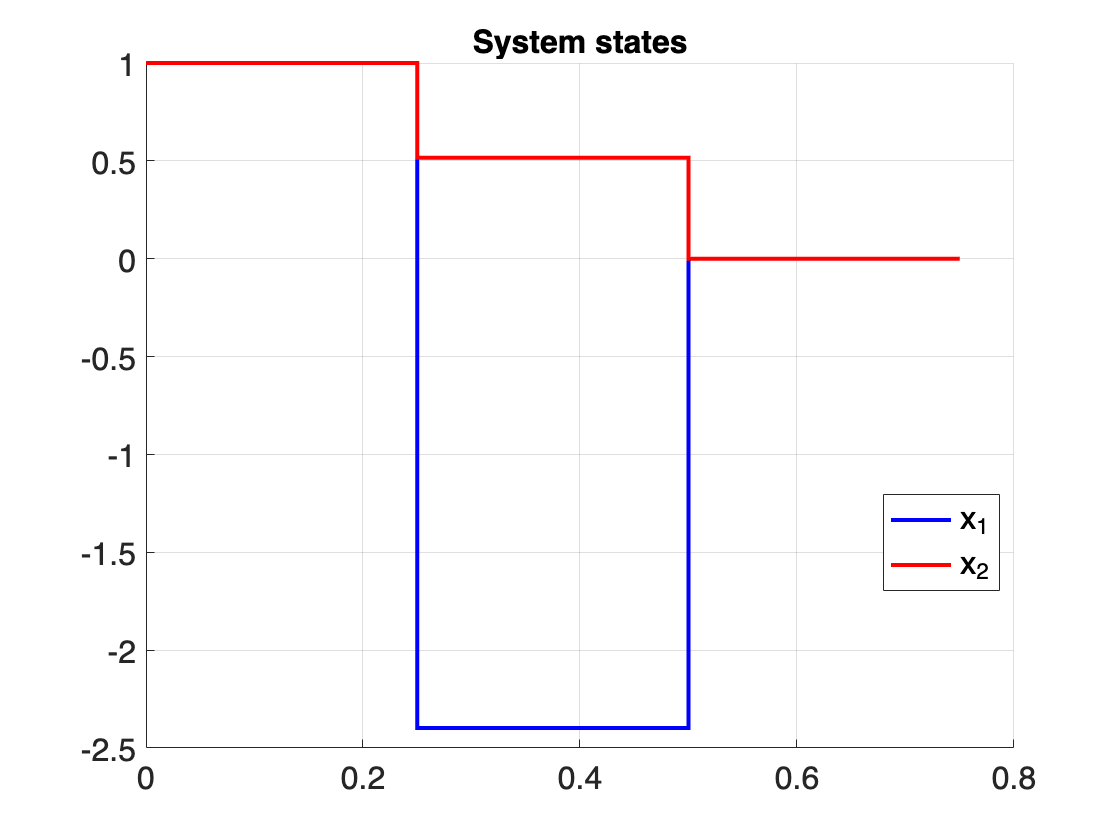

sim_res = sim("task1.slx", 0.75);
clf;
title("System states");
hold on;
stairs(sim_res.x.time, sim_res.x.data(:,1), 'LineWidth', 2, 'Color', 'blue', 'LineStyle', '-');
stairs(sim_res.x.time, sim_res.x.data(:,2), 'LineWidth', 2, 'Color', 'red', 'LineStyle', '-');
grid on;
legend({'x_1', 'x_2'}, 'Location', 'best');
fontsize(16, "points");
hold off;
exportgraphics(gcf, SAVE_DIR + "task1" + SAVE_EXT);

## Task 2

A_gen = [0 omega_g; -omega_g 0];
ss_gen = ss(A_gen, [0; 0], [A_g 0], 0);
ss_gen_disc = c2d(ss_gen, T)

ss_gen_disc =
 
  A = 
             x1        x2
   x1    0.9972   0.07493
   x2  -0.07493    0.9972
 
  B = 
       u1
   x1   0
   x2   0
 
  C = 
         x1    x2
   y1  7.68     0
 
  D = 
       u1
   y1   0
 
Sample time: 0.25 seconds
Discrete-time state-space model.


ss_obsv = compreal(ss_plant_discrete, "o")

ss_obsv =
 
  A = 
            x1       x2
   x1        0        1
   x2  -0.4034    1.297
 
  B = 
          u1
   x1  4.229
   x2  8.608
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Sample time: 0.25 seconds
Discrete-time state-space model.


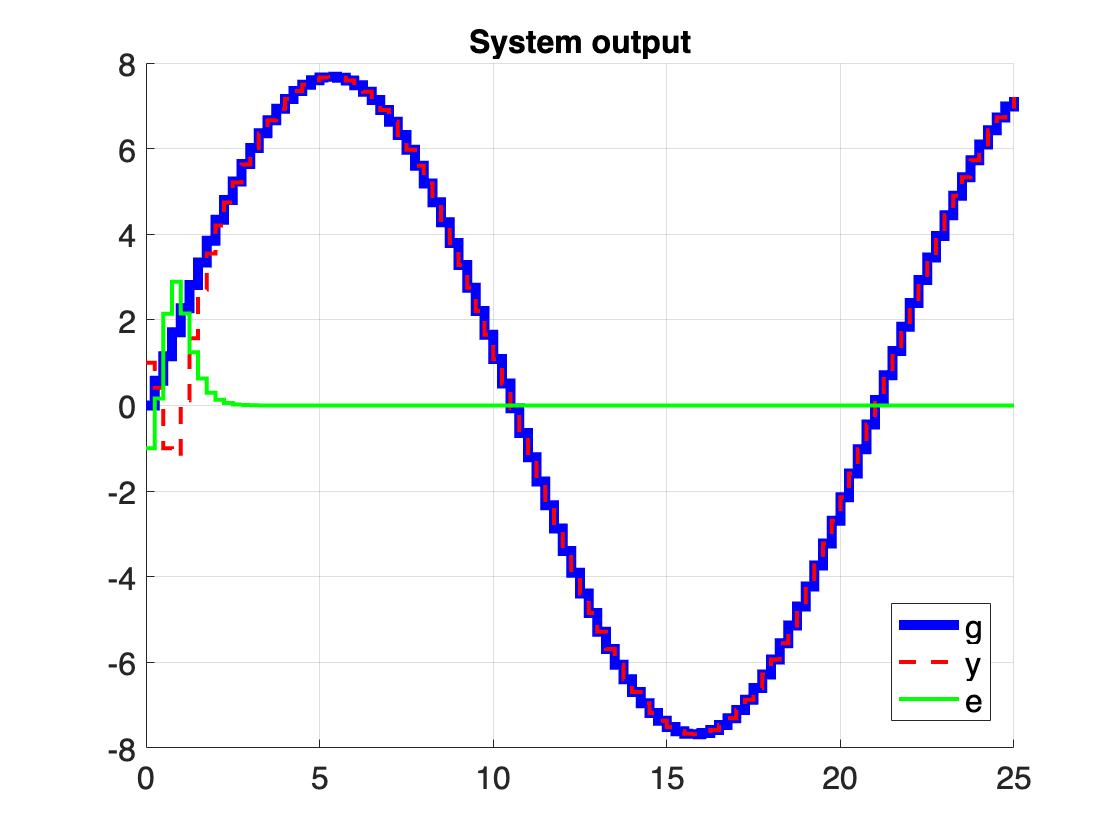

B_eta = [1; 1];
assert(rank(ctrb(ss_gen_disc.A, B_eta)) == 2);
Gamma = ss_gen_disc.A;

A_bar = [Gamma -B_eta * ss_obsv.C; zeros(2, 2) ss_obsv.A];
B_bar = [0; 0; ss_obsv.B];
B_1_bar = [B_eta; 0; 0];
K_bar = place(A_bar, B_bar, [0.1 0.2 0.3 0.4]);
B_g_bar = B_1_bar + K_bar(1) * B_bar;

F_bar = A_bar - B_bar * K_bar;

sim_res = sim("task2.slx", 25);
clf;
title("System output");
hold on;
stairs(sim_res.gen_d.time, sim_res.gen_d.data, 'LineWidth', 5, 'Color', 'blue', 'LineStyle', '-');
stairs(sim_res.y.time, sim_res.y.data, 'LineWidth', 2, 'Color', 'red', 'LineStyle', '--');
stairs(sim_res.y.time, sim_res.gen_d.data - sim_res.y.data, 'LineWidth', 2, 'Color', 'green', 'LineStyle', '-');
grid on;
legend({'g', 'y', 'e'}, 'Location', 'best');
fontsize(16, "points");
hold off;
exportgraphics(gcf, SAVE_DIR + "task2_system" + SAVE_EXT);

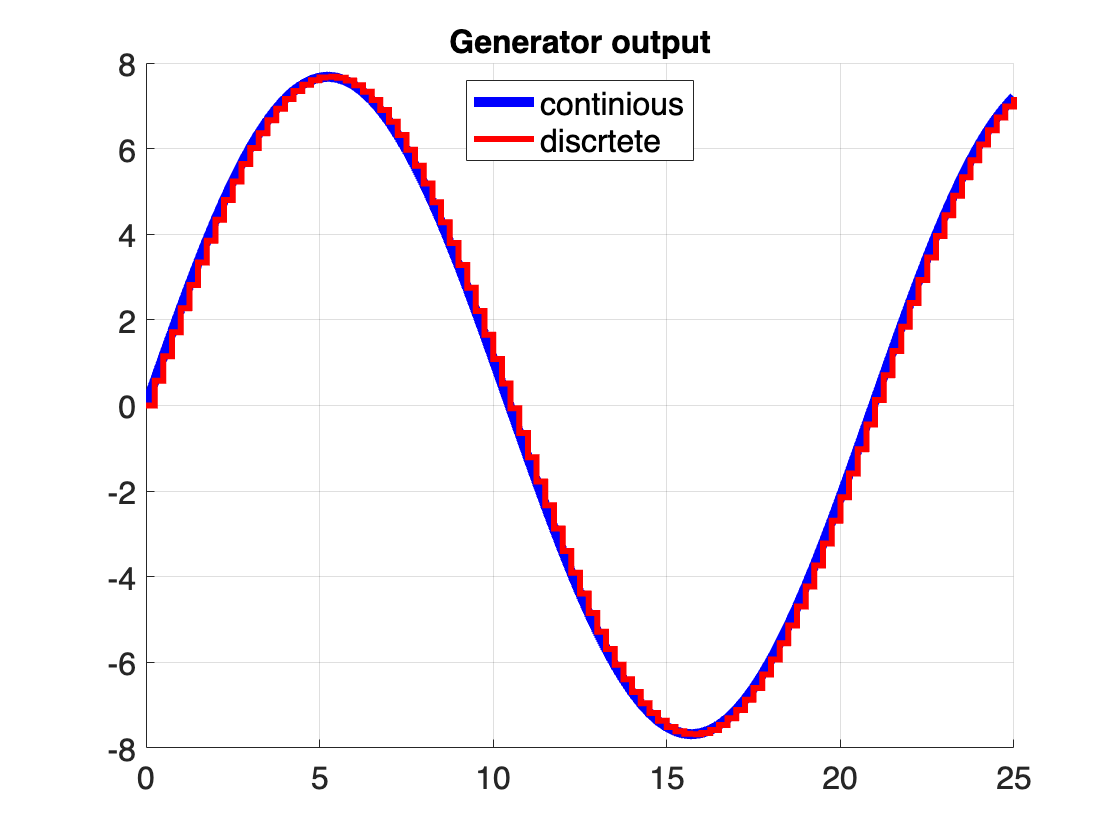


clf;
title("Generator output");
hold on;
plot(sim_res.gen_c.time, sim_res.gen_c.data, 'LineWidth', 5, 'Color', 'blue', 'LineStyle', '-');
stairs(sim_res.gen_d.time, sim_res.gen_d.data, 'LineWidth', 3, 'Color', 'red', 'LineStyle', '-');
grid on;
legend({'continious', 'discrtete'}, 'Location', 'best');
fontsize(16, "points");
hold off;
exportgraphics(gcf, SAVE_DIR + "task2_generator" + SAVE_EXT);

A_bar, B_bar, K_bar, eig(A_bar - B_bar * K_bar)

A_bar =     0.9972    0.0749   -1.0000         0
   -0.0749    0.9972   -1.0000         0
         0         0         0    1.0000
         0         0   -0.4034    1.2967


B_bar =          0
         0
    4.2286
    8.6085


K_bar =    -0.3568    0.1592    0.1383    0.1982


ans =     0.4000
    0.3000
    0.2000
    0.1000


## Task 3

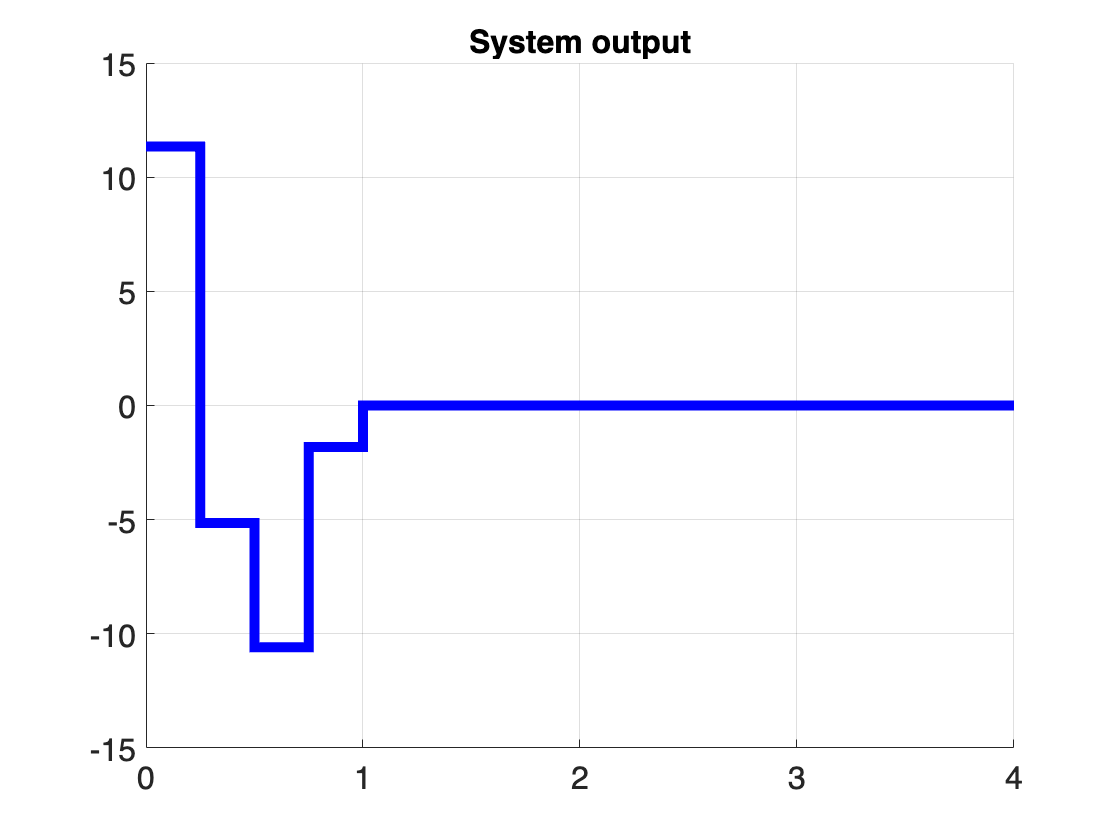

assert(rank(obsv(ss_plant_discrete.A, ss_plant_discrete.C)) == 2);
Gamma_o = [0.0 1; 0 0];
H = [1 1];
assert(rank(obsv(Gamma_o, H)) == 2);
M = sylvester(ss_plant_discrete.A', -Gamma_o, ss_plant_discrete.C' * H);
L = H / M;
sim_res = sim("task3_1.slx", 4);

clf;
title("System output");
hold on;
stairs(sim_res.y.time, sim_res.y.data, 'LineWidth', 5, 'Color', 'blue', 'LineStyle', '-');
grid on;
fontsize(16, "points");
hold off;
exportgraphics(gcf, SAVE_DIR + "task3_1_y" + SAVE_EXT);

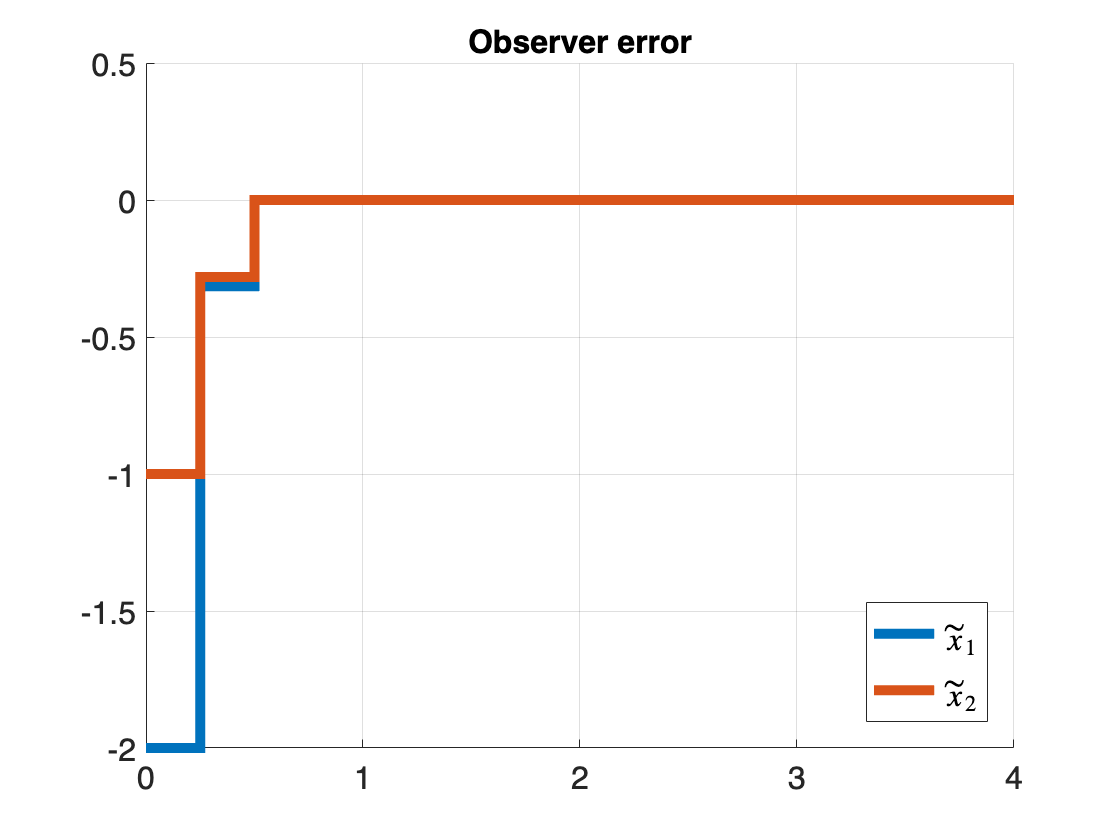

u =
   -0.9705

u =
   -0.4024

u =
   -0.1842

u =
   -0.0238

u =
    0.3239

u =
    0.7501

u =
    1.2073

u =
    1.6887

u =
    2.1846

u =
    2.6895

u =
    3.2033

u =
    3.7278

u =
    4.2642

u =
    4.8128

u =
    5.3725

u =
    5.9405

u =
    6.5130

u =
    7.0857

u =
    7.6538

u =
    8.2129

u =
    8.7585

u =
    9.2867

u =
    9.7938

u =
   10.2765

u =
   10.7315

u =
   11.1561

u =
   11.5475

u =
   11.9031

u =
   12.2205

u =
   12.4975

u =
   12.7320

u =
   12.9223

u =
   13.0668

u =
   13.1643

u =
   13.2137

u =
   13.2144

u =
   13.1659

u =
   13.0681

u =
   12.9212

u =
   12.7255

u =
   12.4818

u =
   12.1911

u =
   11.8546

u =
   11.4740

u =
   11.0508

u =
   10.5872

u =
   10.0854

u =
    9.5479

u =
    8.9774

u =
    8.3767

u =
    7.7489

u =
    7.0972

u =
    6.4249

u =
    5.7356

u =
    5.0327

u =
    4.3199

u =
    3.6009

u =
    2.8796

u =
    2.1595

u =
    1.4446

u =
    0.7385

u =
    0.0449

u =
   -

clf;
title("Observer error");
hold on;
stairs(sim_res.x_tilde.time, sim_res.x_tilde.data, 'LineWidth', 5, 'LineStyle', '-');
grid on;
legend({'$$\tilde x_1$$', '$$\tilde x_2 $$'}, 'Location', 'best', 'Interpreter','latex');
fontsize(16, "points");
hold off;
exportgraphics(gcf, SAVE_DIR + "task3_1_e" + SAVE_EXT);

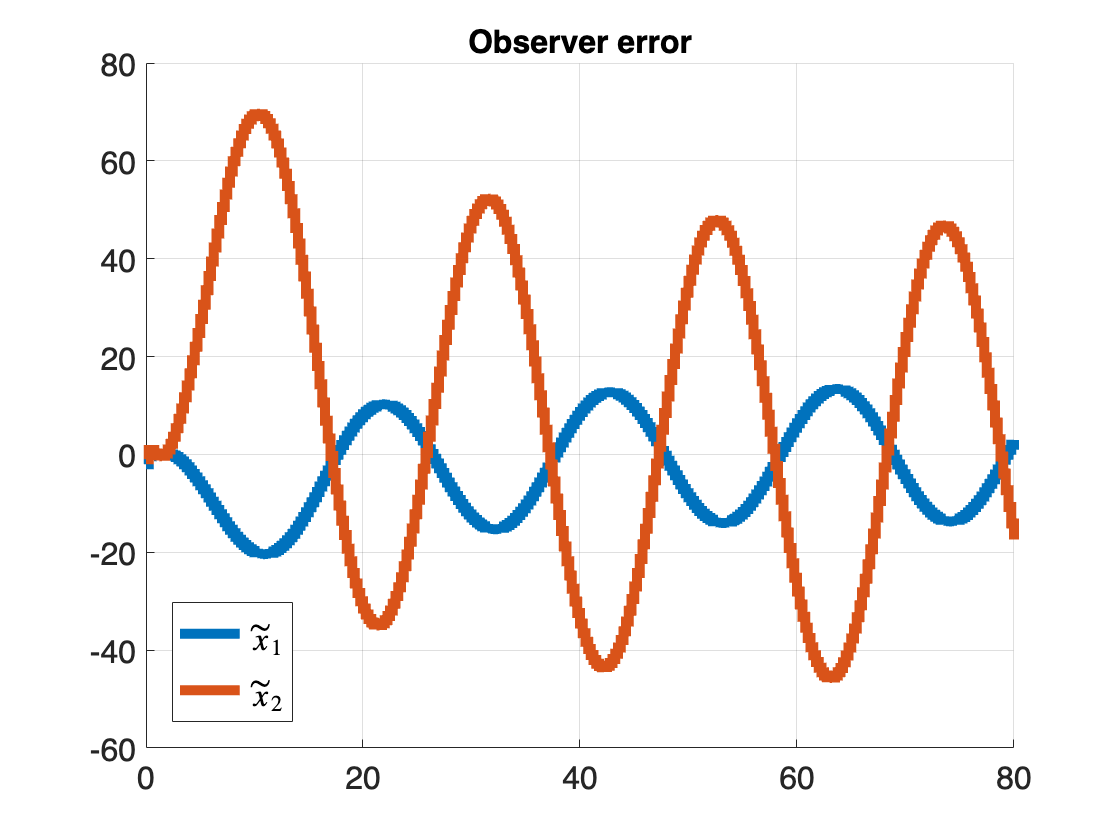

sim_res = sim("task3_2.slx", 80);
clf;
title("Observer error");
hold on;
stairs(sim_res.x_tilde.time, sim_res.x_tilde.data, 'LineWidth', 5, 'LineStyle', '-');
grid on;
legend({'$$\tilde x_1$$', '$$\tilde x_2 $$'}, 'Location', 'best', 'Interpreter','latex');
fontsize(16, "points");
hold off;
exportgraphics(gcf, SAVE_DIR + "task3_2_e" + SAVE_EXT);

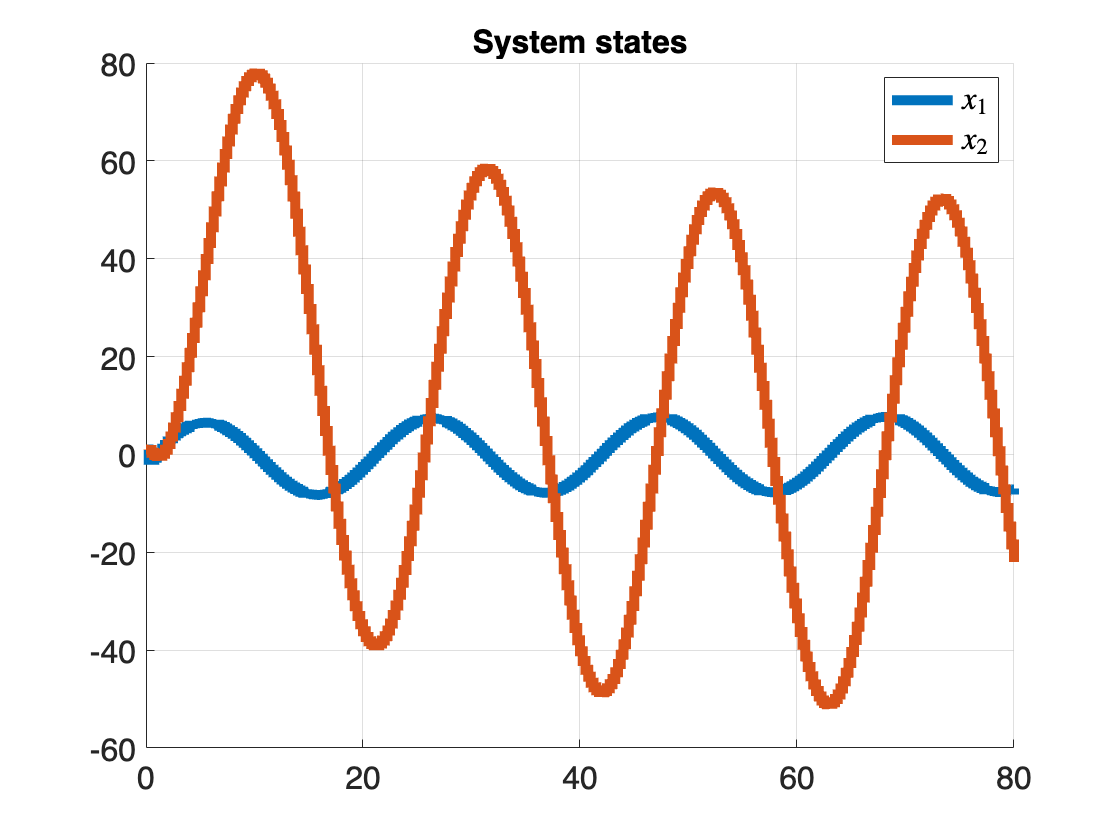

clf;
title("System states");
hold on;
stairs(sim_res.x.time, sim_res.x.data, 'LineWidth', 5, 'LineStyle', '-');
grid on;
legend({'$$x_1$$', '$$x_2 $$'}, 'Location', 'best', 'Interpreter','latex');
fontsize(16, "points");
hold off;
exportgraphics(gcf, SAVE_DIR + "task3_2_x" + SAVE_EXT);

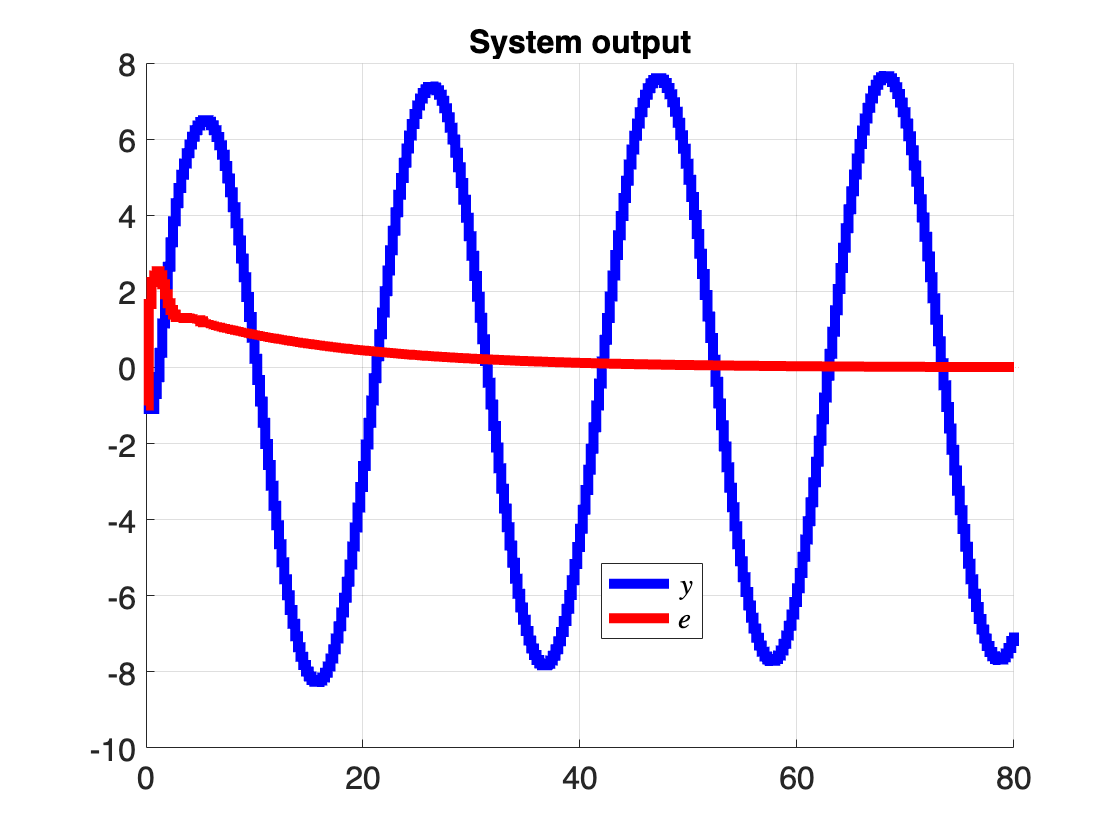

clf;
title("System output");
hold on;
stairs(sim_res.y.time, sim_res.y.data, 'LineWidth', 5, 'Color', 'blue', 'LineStyle', '-');
stairs(sim_res.e.time, sim_res.e.data, 'LineWidth', 5, 'Color', 'red', 'LineStyle', '-');
grid on;
fontsize(16, "points");
legend({'$$y$$', '$$e $$'}, 'Location', 'best', 'Interpreter','latex');
hold off;
exportgraphics(gcf, SAVE_DIR + "task3_2_y" + SAVE_EXT);